close all; clear all; clc
cd(fileparts(matlab.desktop.editor.getActiveFilename));
cd("..\data-engineering\")

data_dir = "D:/FRM/co-adaptive-learning/";
participant_list = ["p-10/healthy/hl/", "p-11/healthy/hl/", "p-12/healthy/hl/", "p-13/healthy/hl/", "p-14/healthy/hl/"];
participant_list = ["p-05/nonparetic/ml/", "p-06/nonparetic/ml/", "p-07/nonparetic/ml/", "p-08/nonparetic/ml/", "p-09/nonparetic/ml/"];
% participant_list = ["p-10/healthy/cl/", "p-11/healthy/cl/", "p-12/healthy/cl/", "p-13/healthy/cl/", "p-14/healthy/cl/"];
% participant_list = ["p-10/healthy/ml/", "p-11/healthy/ml/", "p-12/healthy/ml/", "p-13/healthy/ml/", "p-14/healthy/ml/"];
kdf_regex = "Task*.kdf";
kef_regex = "Event*.txt";
ns5_regex = "*.ns5";
single_chan_idx = 192 + [1,2,3,4,11,12,13,14,21,22,23,24,31,32,33,34,41,42,43,44,51,52,53,54,61,62,63,64,71,72,73,74];
% single_chan_idx = 192 + [1:528];

for i=1:length(participant_list)
    disp(i)
    participant_dir = participant_list(i);
    dir_out = dir(strcat(data_dir, participant_dir, kdf_regex));
    participant_kdf_file = strcat(data_dir, participant_dir, dir_out.name)
    dir_out = dir(strcat(data_dir, participant_dir, kef_regex));
    participant_kef_file = strcat(data_dir, participant_dir, dir_out.name)
    dir_out = dir(strcat(data_dir, participant_dir, ns5_regex));
    participant_ns5_file = convertStringsToChars(strcat(data_dir, participant_dir, dir_out.name))
    [Kinematics, Features, Targets, Kalman, NIPTime] = jag_deng_utils.read_kdf_file(participant_kdf_file);
    events_kef = jag_deng_utils.read_event_params(participant_kef_file);
    % [ns5_header, ns5_data] = jag_deng_utils.read_nsx_file('File', participant_ns5_file);
    % ns5_length = length(ns5_data);
    % downsampled_idxs = 1:1e4:ns5_length;

    event_starts_nip = uint32([events_kef.TargOnTS]');
    event_stops_nip = uint32([events_kef.TrialTS])';
    event_stops_nip = event_stops_nip(1:end-1);
    trial_starts_nip = event_starts_nip(1:3:end);
    trial_stops_nip = event_stops_nip(2:3:end);
    coact_starts_nip = event_starts_nip(1:3:end);
    coact_stops_nip = event_stops_nip(1:3:end);
    diffact_starts_nip = event_starts_nip(2:3:end);
    diffact_stops_nip = event_stops_nip(2:3:end);

## DEng: Long Timetable

    for trial_num = 1:length(trial_starts_nip)
        trial_starts_idx = find(ismember(NIPTime, trial_starts_nip(trial_num)));
        trial_stops_idx = find(ismember(NIPTime, trial_stops_nip(trial_num)));
        trial_idxs = trial_starts_idx:trial_stops_idx;
        trial_tbl = table(NIPTime(trial_idxs)', Targets(1:5,trial_idxs)', Features(single_chan_idx,trial_idxs)', Kalman(1:5, trial_idxs)', ...
            'VariableNames', ["NIP Time", "Targets", "MAV Features", "Kalman Inferences"]);
        if "ml" == regexp(participant_dir,"ml", 'match')
            trial_tbl.("Trial Number") = repmat(trial_num-1,height(trial_tbl),1);
        else
            trial_tbl.("Trial Number") = repmat(trial_num,height(trial_tbl),1);
        end

        coact_starts_idx = find(ismember(trial_tbl.("NIP Time"), coact_starts_nip(trial_num)));
        coact_stops_idx = find(ismember(trial_tbl.("NIP Time"), coact_stops_nip(trial_num)));
        diffact_starts_idx = find(ismember(trial_tbl.("NIP Time"), diffact_starts_nip(trial_num)));
        diffact_stops_idx = find(ismember(trial_tbl.("NIP Time"), diffact_stops_nip(trial_num)));
        trial_tbl.("Gesture") = repmat("N/A", height(trial_tbl),1);
        trial_tbl.("Gesture")(coact_starts_idx:coact_stops_idx) = "Co-Activation";
        trial_tbl.("Gesture")(diffact_starts_idx:diffact_stops_idx) = "Differential Activation";

        if trial_num ==1
            session_tbl  = trial_tbl;
        else
            session_tbl = [session_tbl; trial_tbl];
        end
    end

## Fig: Stitched Session

    session_ttbl = table2timetable(session_tbl, 'TimeStep', duration(0,0,0,30));
    session_ttbl = normalize(session_ttbl,'range', 'DataVariables', "MAV Features");
    figure();
    hold on
    plot(session_ttbl.Time, session_ttbl.("MAV Features"))
    plot(session_ttbl.Time, session_ttbl.("Targets"))
    plot(session_ttbl.Time, mean(session_ttbl.("MAV Features"),2), Color='k', LineWidth=3)
    hold off

## Fig: Mean Trial MAV

    fig_h = figure();
    tlo = tiledlayout('flow');
    for trial_num = unique(session_ttbl.("Trial Number"))'
        trial_ttbl = session_ttbl(session_ttbl.("Trial Number")==trial_num,:);
        if trial_num ~=0
            nexttile
            hold on
            plot(trial_ttbl.("MAV Features"))
            plot(trial_ttbl.("Targets"), LineWidth=2)
            plot(mean(trial_ttbl.("MAV Features"),2), Color='k', LineWidth=3)
            hold off
            title(sprintf("T%02d", trial_num))
        end
    end
    title(tlo, dir_to_str(participant_dir))
    saveas(fig_h, sprintf("../../results/%s-mav.png", dir_to_str(participant_dir)))

## Fig: Mean Trial Heatmap

    fig_h = figure();
    tlo = tiledlayout('flow');
    for trial_num = unique(session_ttbl.("Trial Number"))'
        trial_ttbl = session_ttbl(session_ttbl.("Trial Number")==trial_num,:);
        coact_features = trial_ttbl(trial_ttbl.("Gesture") == "Co-Activation", "MAV Features");
        diffact_features = trial_ttbl(trial_ttbl.("Gesture") == "Differential Activation", "MAV Features");
        coact_means = mean(coact_features{:,:})';
        diffact_means = mean(diffact_features{:,:})';
        if trial_num ~=0
            nexttile
            heatmap([coact_means, diffact_means], Colormap=copper)
            clim([0,1])
            title(sprintf("T%02d", trial_num))
        end
        if trial_num == 1
            coact_means_1 = coact_means;
            diffact_means_1 = diffact_means;
        end
        if trial_num == 9
            coact_means_9 = coact_means;
            diffact_means_9 = diffact_means;
        end
    end
    title(tlo, dir_to_str(participant_dir))
    saveas(fig_h, sprintf("../../results/%s-heat.png", dir_to_str(participant_dir)))

## Fig: Mean MAV Correlation Plot

    fig_h = figure();
    hold on
    plot(coact_means_1, diffact_means_1, 'r*')
    coeffs_1 = polyfit(coact_means_1, diffact_means_1,1);
    diffact_fit_1 = polyval(coeffs_1, coact_means_1);
    plot(coact_means_1, diffact_fit_1, 'r', LineWidth=2)
    plot(coact_means_9, diffact_means_9, 'm*')
    coeffs_9 = polyfit(coact_means_9, diffact_means_9, 1);
    diffact_fit_9 = polyval(coeffs_9, coact_means_9);
    plot(coact_means_9, diffact_fit_9, 'm', LineWidth=2)
    hold off
    legend([sprintf("Trial 1: Slope = %0.2f", coeffs_1(1)), "", sprintf("Trial 9: Slope = %0.2f", coeffs_9(1)),""], Location="northwest")
    xlabel("Mean MAV of Channels During Co-Activation")
    ylabel("Mean MAV of Channels During Differential Activation")
    axis square
    title(dir_to_str(participant_dir))
    saveas(fig_h, sprintf("../../results/%s-corr.png", dir_to_str(participant_dir)))

## Fig: Trial Inferences

    fig_h = figure();
    tlo = tiledlayout('flow');
    for trial_num = unique(session_ttbl.("Trial Number"))'
        trial_ttbl = session_ttbl(session_ttbl.("Trial Number")==trial_num,:);
        if trial_num ~=0
            nexttile
            hold on
            plot(mean(trial_ttbl.("MAV Features"),2), Color='k', LineWidth=3)
            plot(trial_ttbl.("Kalman Inferences"))
            plot(trial_ttbl.("Targets"), LineWidth=2)
            hold off
            title(sprintf("T%02d", trial_num))
        end
    end
    title(tlo, dir_to_str(participant_dir))
    saveas(fig_h, sprintf("../../results/%s-kalman.png", dir_to_str(participant_dir)))

## Fig: PCA Projections

    [coeff,score,latent,tsquared,explained,mu] = pca(session_ttbl.("MAV Features"));
    cumsum(explained)
    projected_session_ttbl = session_ttbl;
    projected_session_ttbl.("Projected MAV") = session_ttbl.("MAV Features")*coeff(:,1:3);
    fig_h = figure();
    tlo = tiledlayout('flow');
    for trial_num = unique(session_ttbl.("Trial Number"))'
        trial_ttbl = projected_session_ttbl(session_ttbl.("Trial Number")==trial_num,:);
        coact_features = trial_ttbl(trial_ttbl.("Gesture") == "Co-Activation", "Projected MAV");
        diffact_features = trial_ttbl(trial_ttbl.("Gesture") == "Differential Activation", "Projected MAV");
        coact_centroid = mean(coact_features{:,:})';
        diffact_centroid = mean(diffact_features{:,:})';
        if trial_num ~=0
            nexttile
            hold on
            plot3( coact_features.("Projected MAV")(:,1),coact_features.("Projected MAV")(:,2), coact_features.("Projected MAV")(:,3), '.', Color="#0072BD")
            plot3( coact_centroid(1), coact_centroid(2), coact_centroid(3), 'bo', MarkerSize=10, LineWidth=3)
            plot3( diffact_features.("Projected MAV")(:,1),diffact_features.("Projected MAV")(:,2), diffact_features.("Projected MAV")(:,3), '.', Color="#A2142F")
            plot3( diffact_centroid(1), diffact_centroid(2), diffact_centroid(3), 'ro', MarkerSize=10, LineWidth=3)
            plot3( [coact_centroid(1); diffact_centroid(1)], [coact_centroid(2); diffact_centroid(2)], [coact_centroid(3); diffact_centroid(3)], LineWidth=3, Color='k')
            hold off
            view([1 1 1])
            title(sprintf("T%02d", trial_num))
            subtitle(sprintf("Euclidean Dist = %0.2f", sqrt(sum((coact_centroid - diffact_centroid).^2))))
        end

    end
    title(tlo, dir_to_str(participant_dir))
    saveas(fig_h, sprintf("../../results/%s-pca.png", dir_to_str(participant_dir)))
end

     1



participant_kdf_file = "D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/TaskData_20230308-181939.kdf"

participant_kef_file = "D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/EventParams_20230308-181939.txt"

participant_ns5_file = 'D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/'

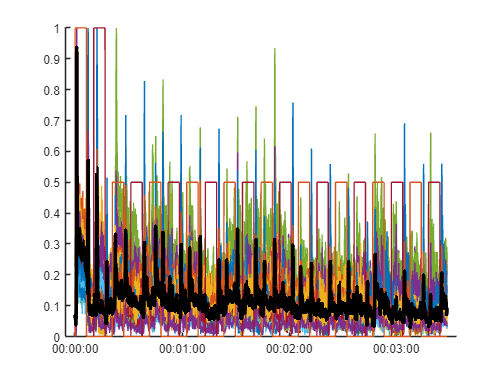

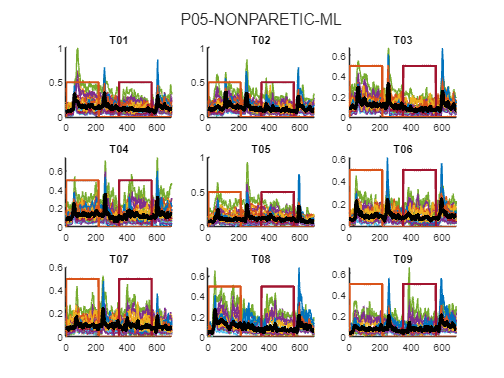

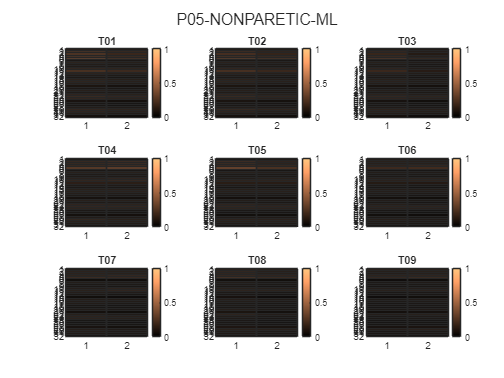

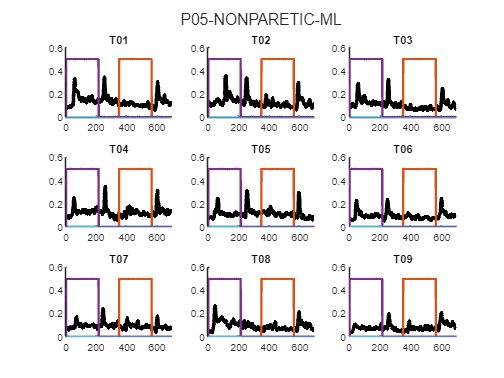

ans =    67.9963
   82.1007
   87.5590
   92.5162
   94.9055
   95.9404
   96.7372
   97.3955
   97.7742
   98.0832


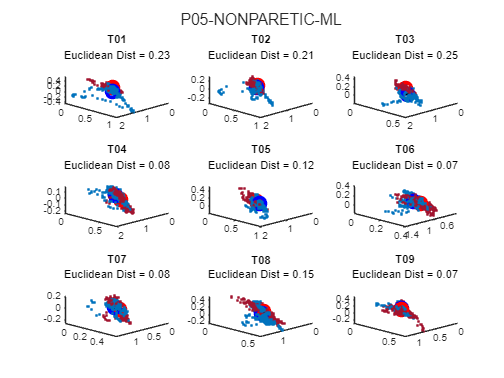

     2



participant_kdf_file = "D:/FRM/co-adaptive-learning/p-06/nonparetic/ml/TaskData_20230310-164347.kdf"

participant_kef_file = "D:/FRM/co-adaptive-learning/p-06/nonparetic/ml/EventParams_20230310-164347.txt"

participant_ns5_file = 'D:/FRM/co-adaptive-learning/p-06/nonparetic/ml/20230310-164347-0005.ns5'

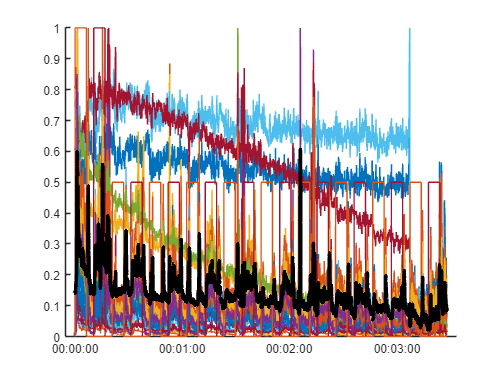

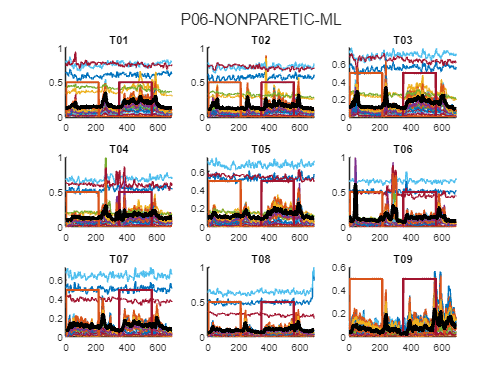

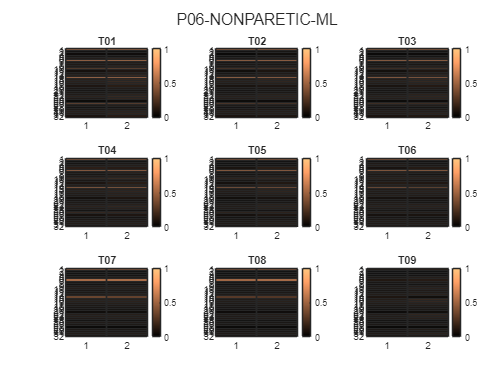

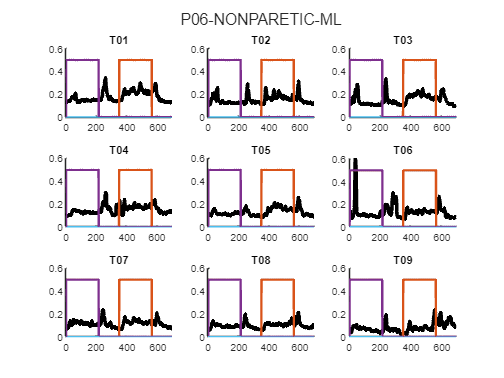

ans =    51.7812
   78.1694
   85.2066
   90.1048
   93.5568
   95.7769
   96.7489
   97.5331
   98.2501
   98.7626


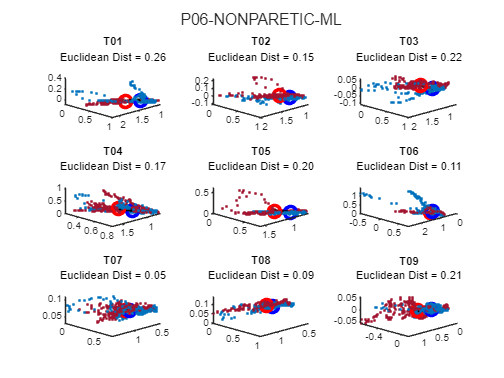

     3



participant_kdf_file = "D:/FRM/co-adaptive-learning/p-07/nonparetic/ml/TaskData_20230313-120910.kdf"

participant_kef_file = "D:/FRM/co-adaptive-learning/p-07/nonparetic/ml/EventParams_20230313-120910.txt"

participant_ns5_file = 'D:/FRM/co-adaptive-learning/p-07/nonparetic/ml/20230313-120910-0019.ns5'

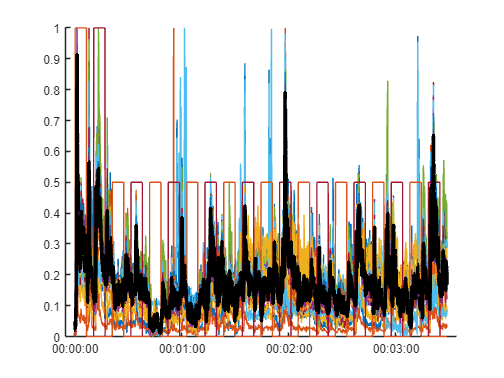

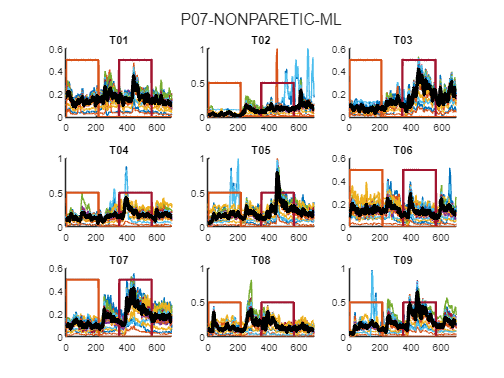

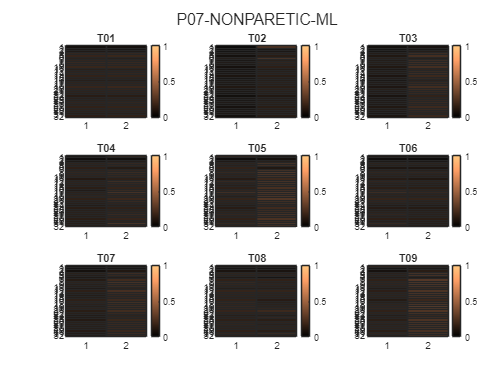

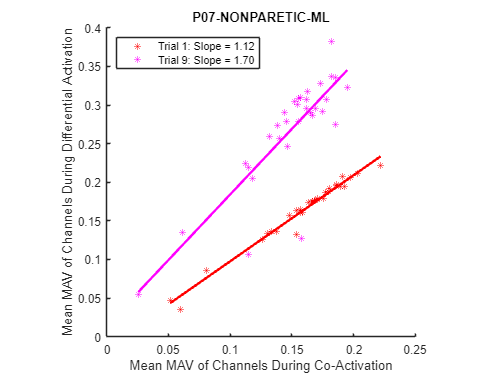

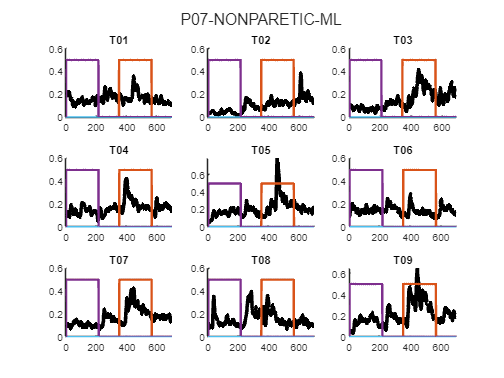

ans =    86.0555
   92.1202
   94.5824
   95.9764
   96.9282
   97.5661
   98.0945
   98.5851
   98.8384
   99.0784


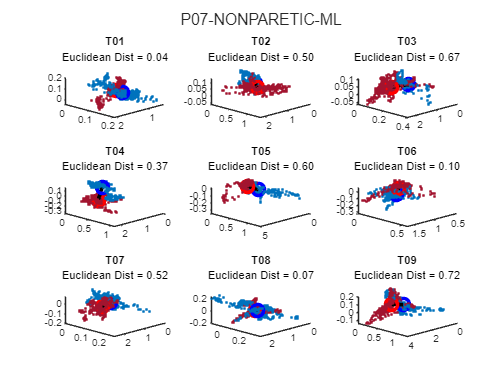

     4



participant_kdf_file = "D:/FRM/co-adaptive-learning/p-08/nonparetic/ml/TaskData_20230504-141815.kdf"

participant_kef_file = "D:/FRM/co-adaptive-learning/p-08/nonparetic/ml/EventParams_20230504-141815.txt"

participant_ns5_file = 'D:/FRM/co-adaptive-learning/p-08/nonparetic/ml/20230504-141815-0001.ns5'

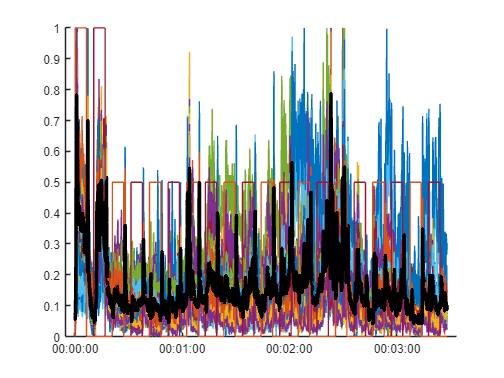

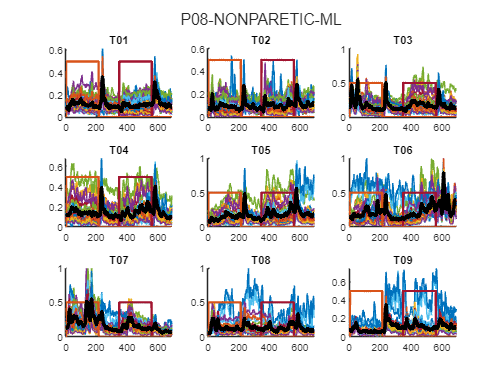

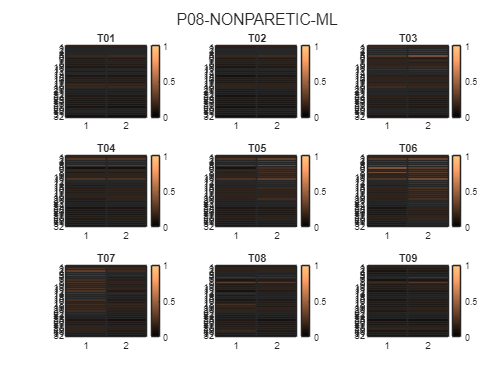

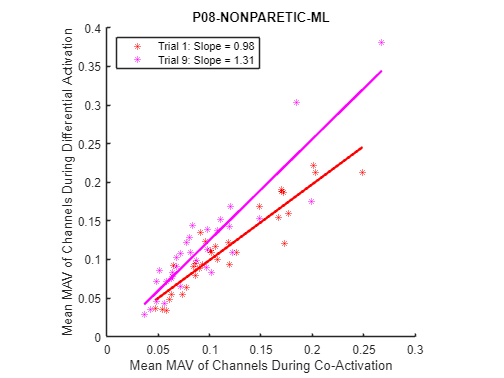

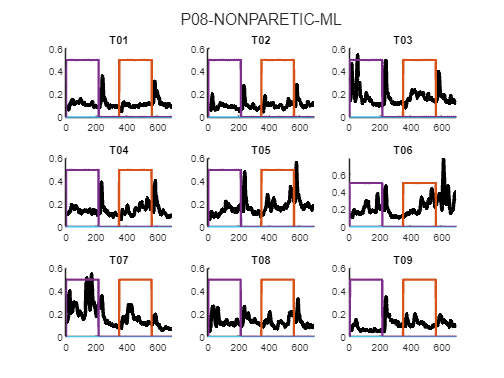

ans =    64.3725
   77.4120
   89.8897
   93.1995
   94.7924
   95.8925
   96.6476
   97.2273
   97.6891
   98.1231


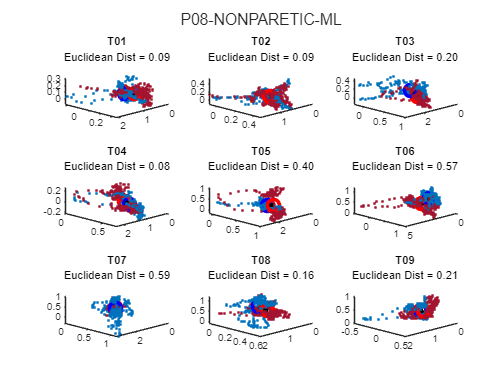

     5



participant_kdf_file = "D:/FRM/co-adaptive-learning/p-09/nonparetic/ml/TaskData_20230517-132109.kdf"

participant_kef_file = "D:/FRM/co-adaptive-learning/p-09/nonparetic/ml/EventParams_20230517-132109.txt"

participant_ns5_file = 'D:/FRM/co-adaptive-learning/p-09/nonparetic/ml/20230517-132109-0005.ns5'

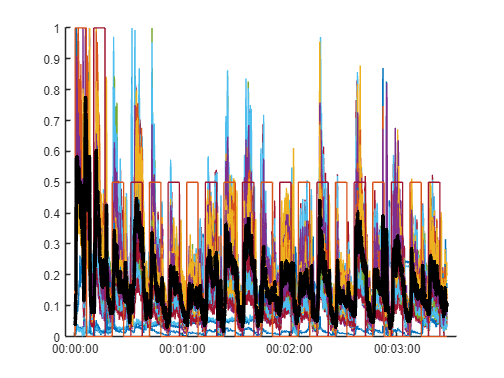

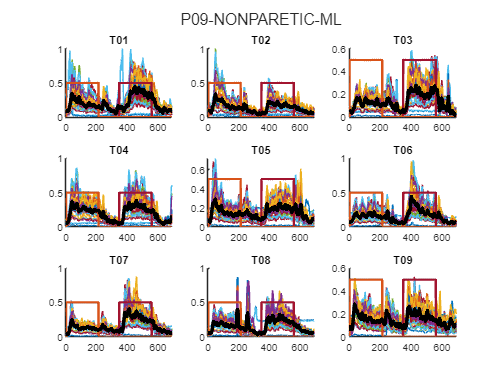

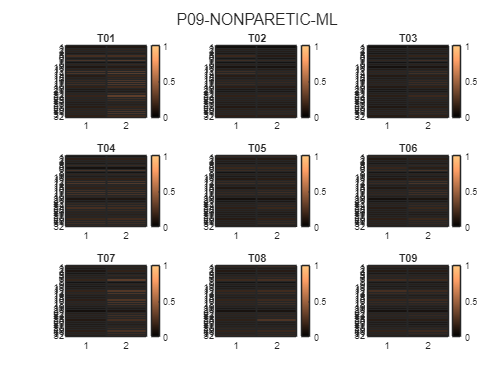

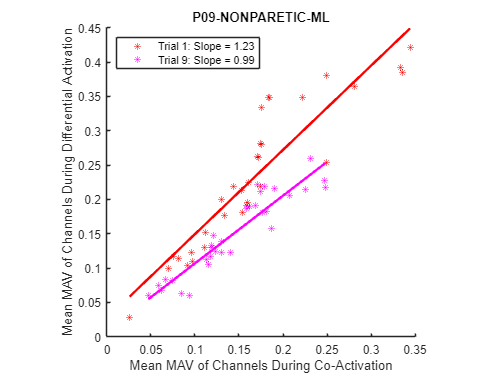

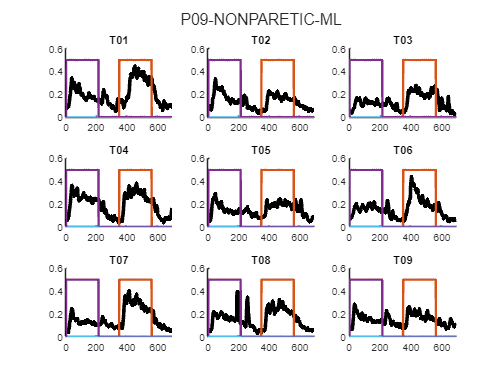

ans =    81.2348
   88.3797
   92.4157
   95.6313
   96.7507
   97.2996
   97.7932
   98.1488
   98.4880
   98.7968


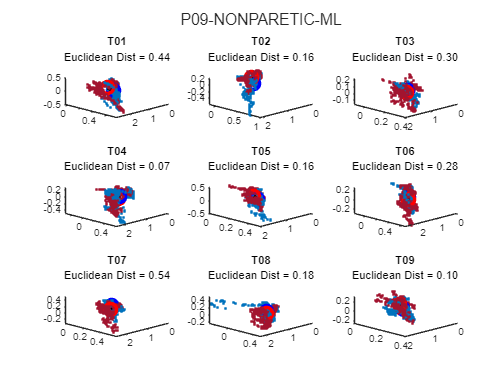

X = session_ttbl{:,"MAV Features"};
X = X(:,std(X)~=0);

X_labels = session_ttbl{:,"Gesture"}+session_ttbl{:,"Trial Number"};
% X_labels = session_ttbl{:,"Trial Number"};
X_labels = session_ttbl{:,"Gesture"};

lda_fit = fitcdiscr(X,X_labels, "DiscrimType","linear")
W = inv(lda_fit.Sigma)*lda_fit.BetweenSigma;
[eig_vecs, eig_vals] = eig(W)
V = [eig_vecs(:,1:3)];

lda_fit =   ClassificationDiscriminant
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'Co-Activation'  'Differential Activation'}
           ScoreTransform: 'none'
          NumObservations: 5483
              DiscrimType: 'linear'
                       Mu: [2×31 double]
                   Coeffs: [2×2 struct]


  Properties, Methods


projected_mav = X*V;
figure();

eig_vecs =    0.0406 + 0.0000i  -0.0047 + 0.0000i  -0.0285 + 0.0000i   0.0312 + 0.0000i   0.0298 - 0.0417i   0.0298 + 0.0417i   0.0520 + 0.0000i   0.0201 - 0.0208i   0.0201 + 0.0208i  -0.0234 + 0.1163i  -0.0234 - 0.1163i   0.2634 - 0.0797i   0.2634 + 0.0797i   0.0514 - 0.0540i   0.0514 + 0.0540i   0.0141 + 0.0099i   0.0141 - 0.0099i   0.1855 + 0.1076i   0.1855 - 0.1076i   0.1334 - 0.0428i   0.1334 + 0.0428i  -0.1635 + 0.0574i  -0.1635 - 0.0574i  -0.2053 + 0.0000i  -0.0248 - 0.0689i  -0.0248 + 0.0689i  -0.1325 + 0.0000i  -0.1150 + 0.0000i  -0.0107 + 0.0000i   0.1028 + 0.0396i   0.1028 - 0.0396i
   0.1397 + 0.0000i  -0.0894 + 0.0000i   0.1696 + 0.0000i   0.2070 + 0.0000i   0.1871 + 0.2479i   0.1871 - 0.2479i   0.1681 + 0.0000i  -0.6152 + 0.0000i  -0.6152 + 0.0000i  -0.3261 + 0.0604i  -0.3261 - 0.0604i  -0.1940 + 0.0244i  -0.1940 - 0.0244i  -0.1068 + 0.0089i  -0.1068 - 0.0089i   0.5001 + 0.0000i   0.5001 + 0.0000i  -0.0682 + 0.0763i  -0.0682 - 0.0763i  -0.1020 + 0.1241i  -0.1020 - 0.1241i

eig_vals =    1.9515 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i

plot3(projected_mav(:,1), projected_mav(:,2), projected_mav(:,3), '.')

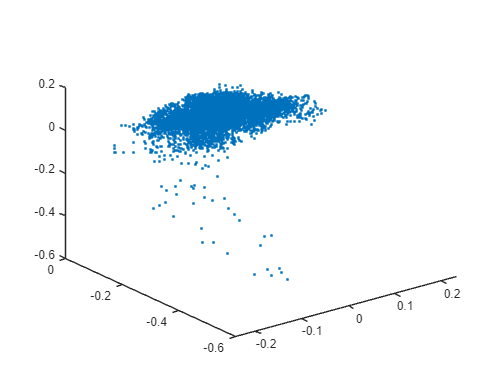

COLOR_THEME = ["#0FC2C0", "#0CABA8", "#008F8C", "#015958", "#023535"];
projected_session_ttbl = session_ttbl;
projected_session_ttbl.("Projected MAV") = X*V;

    fig_h = figure();
    tlo = tiledlayout('flow');
    % nexttile
    % hold on
    for trial_num = unique(session_ttbl.("Trial Number"))'
        trial_ttbl = projected_session_ttbl(session_ttbl.("Trial Number")==trial_num,:);
        coact_features = trial_ttbl(trial_ttbl.("Gesture") == "Co-Activation", "Projected MAV");
        diffact_features = trial_ttbl(trial_ttbl.("Gesture") == "Differential Activation", "Projected MAV");
        coact_centroid = mean(coact_features{:,:})';
        diffact_centroid = mean(diffact_features{:,:})';
        coact_rad = std(coact_features{:,:})';
        diffact_rad = std(diffact_features{:,:})';

        if trial_num ~=0
            nexttile
            hold on
            plot3( coact_features.("Projected MAV")(:,1),coact_features.("Projected MAV")(:,2), coact_features.("Projected MAV")(:,3), '.', Color="#0072BD")
            plot3( coact_centroid(1), coact_centroid(2), coact_centroid(3), 'bo', MarkerSize=10, LineWidth=3)
            plot3( diffact_features.("Projected MAV")(:,1),diffact_features.("Projected MAV")(:,2), diffact_features.("Projected MAV")(:,3), '.', Color="#A2142F")
            plot3( diffact_centroid(1), diffact_centroid(2), diffact_centroid(3), 'ro', MarkerSize=10, LineWidth=3)
            plot3( [coact_centroid(1); diffact_centroid(1)], [coact_centroid(2); diffact_centroid(2)], [coact_centroid(3); diffact_centroid(3)], LineWidth=3, Color='k')
            [X,Y,Z] = ellipsoid(coact_centroid(1), coact_centroid(2), coact_centroid(3), coact_rad(1), coact_rad(2), coact_rad(3));
            sc = surf(X,Y,Z,'facecolor','b','EdgeColor','none','FaceAlpha',.33); 
            [X,Y,Z] = ellipsoid(diffact_centroid(1), diffact_centroid(2), diffact_centroid(3), diffact_rad(1), diffact_rad(2), diffact_rad(3));
            sd = surf(X,Y,Z,'facecolor','r','EdgeColor','none','FaceAlpha',.33);
            text(coact_centroid(1), coact_centroid(2), coact_centroid(3), sprintf("T%02d", trial_num), FontSize=15, FontWeight="bold")
            hold off
            view([1 1 1])
            title(sprintf("T%02d", trial_num))
            subtitle(sprintf("Euclidean Dist = %0.2f, mVARc = %0.2f, mVARd = %0.2f", sqrt(sum((coact_centroid - diffact_centroid).^2)), mean(coact_rad), mean(diffact_rad)))
        end
    end
    % hold off
    title(tlo, dir_to_str(participant_dir))
    % saveas(fig_h, sprintf("../../results/%s-pca.png", dir_to_str(participant_dir)))

## Fig: MAV Series

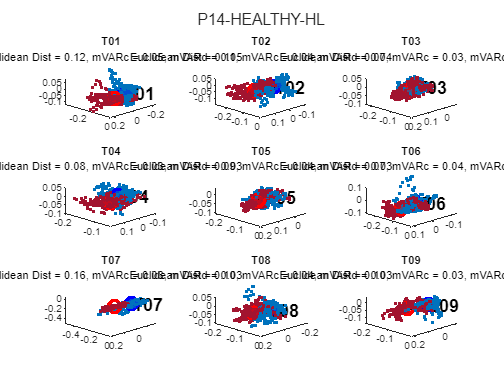

fig_h = figure();
tlo = tiledlayout('flow');

starts_nip = uint32([events_kef.TargOnTS]');
stops_nip = uint32([events_kef.TrialTS])';
stops_nip = stops_nip(1:end-1);
trial_starts_nip = starts_nip(1:3:end);
trial_stops_nip = stops_nip(2:3:end);
session_start_idx = find(ismember(NIPTime, trial_starts_nip(1)))
session_stop_idx = find(ismember(NIPTime, trial_stops_nip(9)))
[good_ft_idxs, feat_norm] = normalize_features(Features(single_chan_idx,session_start_idx:session_stop_idx)', 3000);
for trial=1:9
    trial_start_idx = find(ismember(NIPTime, trial_starts_nip(trial)));
    trial_stop_idx = find(ismember(NIPTime, trial_stops_nip(trial)));
    trial_features = feat_norm(trial_start_idx:trial_stop_idx,:);
    trial_targets = Targets(1:5,  trial_start_idx:trial_stop_idx)'*4;
    nexttile
    hold on
    plot(trial_targets, LineWidth=2)
    plot(trial_features)
    plot(mean(trial_features,2), Color='k', LineWidth=3)
    hold off
    title(sprintf("T%02d", trial))
end
title(tlo, dir_to_str(participant_dir))
saveas(fig_h, sprintf("../../results/%s-mav.png", dir_to_str(participant_dir)))

## Fig:  MAV Heatmaps

fig_h = figure();
tlo = tiledlayout('flow');
[good_ft_idxs, feat_norm] = normalize_features(Features(single_chan_idx,session_start_idx:session_stop_idx)', 5000);
for trial=1:9
    trial_start_idx = find(ismember(NIPTime, trial_starts_nip(trial)));
    trial_stop_idx = find(ismember(NIPTime, trial_stops_nip(trial)));
    trial_features = feat_norm(trial_start_idx:trial_stop_idx,:);
    trial_targets = Targets(1:5,  trial_start_idx:trial_stop_idx)'*4;
    target_idxs = find(diff(sum(trial_targets>0,2))~=0);
    coact_start = target_idxs(1);
    coact_stop =  target_idxs(2);
    diffact_start = target_idxs(3);
    diffact_stop = target_idxs(4);
    nexttile
    coact_means = mean(trial_features(coact_start:coact_stop,:))';
    diffact_means = mean(trial_features(diffact_start:diffact_stop,:))';
    heatmap([coact_means, diffact_means], Colormap=copper)
    clim([-0.5 1.0])
    title(sprintf("T%02d", trial))
    if trial ==1
        coact_means_1 = coact_means;
        diffact_means_1 = diffact_means;
    end
    if trial == 9
        coact_means_9 = coact_means;
        diffact_means_9 = diffact_means;
    end
end
title(tlo, dir_to_str(participant_dir))
saveas(fig_h, sprintf("../../results/%s-heat.png", dir_to_str(participant_dir)))

## Fig: Mean MAV Correlation Plot

fig_h = figure();
hold on
plot(coact_means_1, diffact_means_1, 'r*')
coeffs_1 = polyfit(coact_means_1, diffact_means_1,1);
diffact_fit_1 = polyval(coeffs_1, coact_means_1);
plot(coact_means_1, diffact_fit_1, 'r', LineWidth=2)
plot(coact_means_9, diffact_means_9, 'm*')
coeffs_9 = polyfit(coact_means_9, diffact_means_9, 1);
diffact_fit_9 = polyval(coeffs_9, coact_means_9);
plot(coact_means_9, diffact_fit_9, 'm', LineWidth=2)
hold off
legend([sprintf("Trial 1: Slope = %0.2f", coeffs_1(1)), "", sprintf("Trial 9: Slope = %0.2f", coeffs_9(1)),""], Location="northwest")
xlabel("Mean MAV of Channels During Co-Activation")
ylabel("Mean MAV of Channels During Differential Activation")
axis square
title(dir_to_str(participant_dir))
saveas(fig_h, sprintf("../../results/%s-corr.png", dir_to_str(participant_dir)))
% end

figure();
hold on
plot(feat_norm(:,1))
plot(Targets(1:5,session_start_idx:session_stop_idx)')
plot(mean(feat_norm,2),'k', LineWidth=3)
hold off

emg_raw = ns5_data';
figure
plot(emg_raw(downsampled_idxs,:))
box off

[good_chan_idxs, emg_norm] = clean_and_normalize(emg_raw, 1e4);
figure
plot(emg_norm(downsampled_idxs,:))
box off

[ns5_nip, ns5_idx_starts, ns5_idx_stops] = extract_ns5_event_idxs(events_kef, NIPTime, ns5_length);
figure
plot(ns5_nip(downsampled_idxs), emg_norm(downsampled_idxs,:))
hold on
xline(ns5_nip(ns5_idx_starts))
xline(ns5_nip(ns5_idx_stops), Color="red")
plot(ns5_nip(ismember(ns5_nip, NIPTime)), Targets')
hold off
box off

[trial_start_idxs, trial_stop_idxs]=get_trial_idxs(ns5_idx_starts, ns5_idx_stops);
figure
plot(ns5_nip(downsampled_idxs), emg_norm(downsampled_idxs,:))
hold on
xline(ns5_nip(trial_start_idxs))
xline(ns5_nip(trial_stop_idxs), Color="red")
plot(ns5_nip(ismember(ns5_nip, NIPTime)), Targets')
hold off
box off

[good_ft_idxs, feat_norm] = clean_and_normalize(Features(193:193+31,:)', 5000);


emg_segments = segment_by_trial(emg_norm, trial_start_idxs, trial_stop_idxs);

HHT Analysis

trial_count = 1;
for emg_segment = emg_segments
    trial_signal = emg_segment{1};
    for ch_idx = 1:width(emg_norm)
        trial_channel_signal = trial_signal(:,ch_idx);
        [trial_channel_imf, trial_channel_residual, trial_channel_info] = emd(trial_channel_signal);
        fig_h = figure('Visible','off');
        hht(trial_channel_imf, ns5_header.Fs, "FrequencyLimits",[0,1e3])
        title(sprintf("CH %02d, T%02d", ch_idx, trial_count))
        saveas(fig_h, sprintf("../../results/ch%02d-t%02d.png", ch_idx, trial_count))
    end
    trial_count = trial_count +1;
end

fig_h = figure("Visible","on");
tlo = tiledlayout("flow");
trial_count = 1;
for emg_segment = emg_segments
    nexttile;
    trial_signal = emg_segment{1};
    hold on
    for ch_idx = 1:width(emg_norm)
        trial_channel_signal = trial_signal(:,ch_idx);
        trial_channel_signal = movmean(trial_channel_signal, [300e-3*ns5_header.Fs 0]);
        plot(trial_channel_signal)
        % [trial_channel_imf, trial_channel_residual, trial_channel_info] = emd(trial_channel_signal);
        % hht(trial_channel_imf, ns5_header.Fs, "FrequencyLimits",[0,1e3])
        % saveas(fig_h, sprintf("../../results/ch%02d-t%02d.png", ch_idx, trial_count))
    end
    hold off
    trial_count = trial_count +1;
    title(sprintf("T%02d", trial_count))
end
% saveas(fig_h, sprintf("../../results/mav.png"))

find(good_chan_idxs)
ch_idx=3;
trial_channel_signal = raw_emg_centered(trial_idxs(1):trial_idxs(2), ch_idx);
figure
plot(trial_channel_signal)

[trial_channel_imf, trial_channel_residual, trial_channel_info] = emd(trial_channel_signal);
emd(trial_channel_signal)

figure
stackedplot(trial_channel_imf)

hht(trial_channel_imf, ns5_header.Fs, "FrequencyLimits",[0,1e3])
[hs,f,t,imfinsf,imfinse] = hht(trial_channel_imf, ns5_header.Fs, "FrequencyLimits",[0,1e3]);

% trial_idxs_mav = find(ismember(NIPTime, [start_coact(i), stop_diffact(i)]))
% figure
% plot(mav_features(trial_idxs_mav(1):trial_idxs_mav(2), :))
% hold on
% plot(Targets(:,trial_idxs_mav(1):trial_idxs_mav(2))'*200)


figure
plot(Features(193:193+31,:)')
box off

event_idx = 5;
i_start = find(NIPTime==start_idx(event_idx))
i_stop = find(NIPTime==stop_idx(event_idx))
figure
plot(mean(Features(193:193+10,i_start:i_stop)',2))
hold on
plot(Targets(:, i_start:i_stop)'*100)
hold off

event_idx = 5;
i_start = find(NIPTime==start_idx(event_idx))
i_stop = find(NIPTime==stop_idx(event_idx))
figure
plot(Features(193:193+10,i_start:i_stop)')
hold on
plot(Targets(:, i_start:i_stop)'*100)
hold off

ch_elags = [];
ch_edims = [];
for ch_idx = 1:1:32
    event_idx = 1;
    elags = zeros(27,1);
    edims = zeros(27,1);
    parfor event_idx = 1:1:length(start_idx)
        x_data = ns5_data(ch_idx, start_idx(event_idx):stop_idx(event_idx))';
        [~, elags(event_idx), edims(event_idx) ] = phaseSpaceReconstruction(single(x_data));
    end
    ch_elags = [ch_elags, elags];
    ch_edims = [ch_edims, edims];
end

max_ch_dims =  [ 4     4     5     4     5     4     5     4     5     4     4     4     4     4     4     4     4     5     4     4     5     5     4     5     5     5 5     5     4     4     4     5]

event_idx=25;
X_data = ns5_data( max_ch_dims>4, start_idx(event_idx):stop_idx(event_idx))';

X1_data = movmean(abs(ns5_data( max_ch_dims<=4, start_idx(4):stop_idx(4))'),300e-3*30e3,1);
X2_data = movmean(abs(ns5_data( max_ch_dims<=4, start_idx(13):stop_idx(13))'),300e-3*30e3,1);
X3_data = movmean(abs(ns5_data( max_ch_dims<=4, start_idx(22):stop_idx(22))'),300e-3*30e3,1);
figure
clf
alh1 = animatedline([],[],'Color','r', 'LineStyle',':');
alh2 = animatedline([],[],'Color','b', 'LineStyle',':');
alh3 = animatedline([],[],'Color','k', 'LineStyle',':');
ch = 8;
ylim([0, 600])
xlim([0, 600])
for i = 1:10000:length(X_data)-40
    addpoints(alh1, X1_data(i,ch), X1_data(i+10,ch))
    addpoints(alh2, X2_data(i,ch), X2_data(i+10,ch))
    addpoints(alh3, X3_data(i,ch), X3_data(i+10,ch))
    % pause(0.2)
    drawnow
end

[~, elag, edim ] = phaseSpaceReconstruction(X1_data(:,1))

figure
phaseSpaceReconstruction(X1_data(:,1), elag, edim)

figure
plot(downsample(X1_data, 33e-3*30e3))

## Helper Functions

function [good_chan_idxs, centered_signal] = clean_and_normalize(neural_signal, max_thresh)
good_chan_idxs = ~sum(neural_signal>max_thresh);
disp(strcat("Removed channels: ", mat2str(find(~good_chan_idxs))))
normalized_signal = normalize(neural_signal(:, good_chan_idxs), 1, 'range', [-1, 1]);
centered_signal = normalize(single(normalized_signal), 1, 'center', "mean");
end
function [good_chan_idxs, normalized_signal] = normalize_features(neural_signal, max_thresh)
good_chan_idxs = ~sum(neural_signal>max_thresh);
disp(strcat("Removed channels: ", mat2str(find(~good_chan_idxs))))
normalized_signal = normalize(neural_signal(:, good_chan_idxs), 1, 'range', [0, 1]);
end
function [ns5_nip, ns5_idx_starts, ns5_idx_stops] = extract_ns5_event_idxs(events_kef, NIPTime, ns5_length)
starts_nip = uint32([events_kef.TargOnTS]');
stops_nip = uint32([events_kef.TrialTS])';
stops_nip = stops_nip(1:end-1);
ns5_nip = (NIPTime(1):(NIPTime(1)+ns5_length-1))';
ns5_idx_starts = find(ismember(ns5_nip, starts_nip));
ns5_idx_stops = find(ismember(ns5_nip, stops_nip));
end
function [trial_start_idxs, trial_stop_idxs] = get_trial_idxs(ns5_idx_starts, ns5_idx_stops)
trial_start_idxs = ns5_idx_starts(1:3:end);
trial_stop_idxs = ns5_idx_stops(2:3:end);
end
function [emg_segments] = segment_by_trial(emg_norm, trial_start_idxs, trial_stop_idxs)
emg_segments = {};
for i=1:length(trial_start_idxs)
    emg_segments{i} = emg_norm(trial_start_idxs(i):trial_stop_idxs(i),:);
end
end
function output_str = dir_to_str(input_dir)
parts = strsplit(input_dir, '/');
if length(parts) == 4
    output_str = [erase(upper(parts{1}), '-') '-' upper(parts{2}) '-' upper(parts{3})];
end
end